## Mario de Miguel Domínguez

## DNI 02569059M

# Ejercicio 1 Parcial 2

## Apartado a)

%Empiezo por definir el sistema
syms x1 x2 real positive
system(1, 1) = -x1^2 + 1/x2;
system(2, 1) = x1/x2 - 1;
system

$$system = \left(\begin{array}{c} \frac{1}{x_{2}}-{x_{1}}^{2}\\ \frac{x_{1}}{x_{2}}-1 \end{array}\right)$$

%Obtengo los puntos de equilibrio
[x10, x20] = solve(system);
x0 = [x10; x20]

$$x0 = \left(\begin{array}{c} 1\\ 1 \end{array}\right)$$

Solo hay un punto de equilibrio real positivo: x0 = (1 1).

%Voy a linealizar alrededor de x0 
J = jacobian(system, [x1, x2])

$$J = \left(\begin{array}{cc} -2\,x_{1} & -\frac{1}{{x_{2}}^{2}}\\ \frac{1}{x_{2}} & -\frac{x_{1}}{{x_{2}}^{2}} \end{array}\right)$$

Je = subs(J, {x1, x2}, {x10, x20}) %Ya tengo el jacobiano evaluado en el punto de equilibrio

$$Je = \left(\begin{array}{cc} -2 & -1\\ 1 & -1 \end{array}\right)$$

E = eig(Je) %Miro los autovalores

$$E = \left(\begin{array}{c} -\frac{3}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{3}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

Los dos autovalores del jacobiano en (1 1) tienen ambos parte real negativa, lo que indica que el punto se trata de un foco estable. 

## Apartado b)

%Voy a usar el sistema linealizado en el apartado anterior, cuyas
%ecuaciones vendrán descritas por xdot = Je * x
%Calculo una matriz que satisfaga la ecuación de Lyapunov para el sistema lineal (Je'P + PJe = -Q), que teniendo autovalores con parte real negativa, 
%deberá ser exponencialmente estable (-Q = -I)
P = lyap(Je, eye(2));
%Y con esta matriz P, puedo calcular V asegurando que sea cuadrática en ambas componentes como
V = simplify([x1 - 1,  x2 - 1]*P*[x1 - 1; x2 - 1])

$$V = -\left(x_{1}-1\right)\,\left(\frac{x_{2}}{18}-\frac{5\,x_{1}}{18}+\frac{2}{9}\right)-\left(x_{2}-1\right)\,\left(\frac{x_{1}}{18}-\frac{4\,x_{2}}{9}+\frac{7}{18}\right)$$

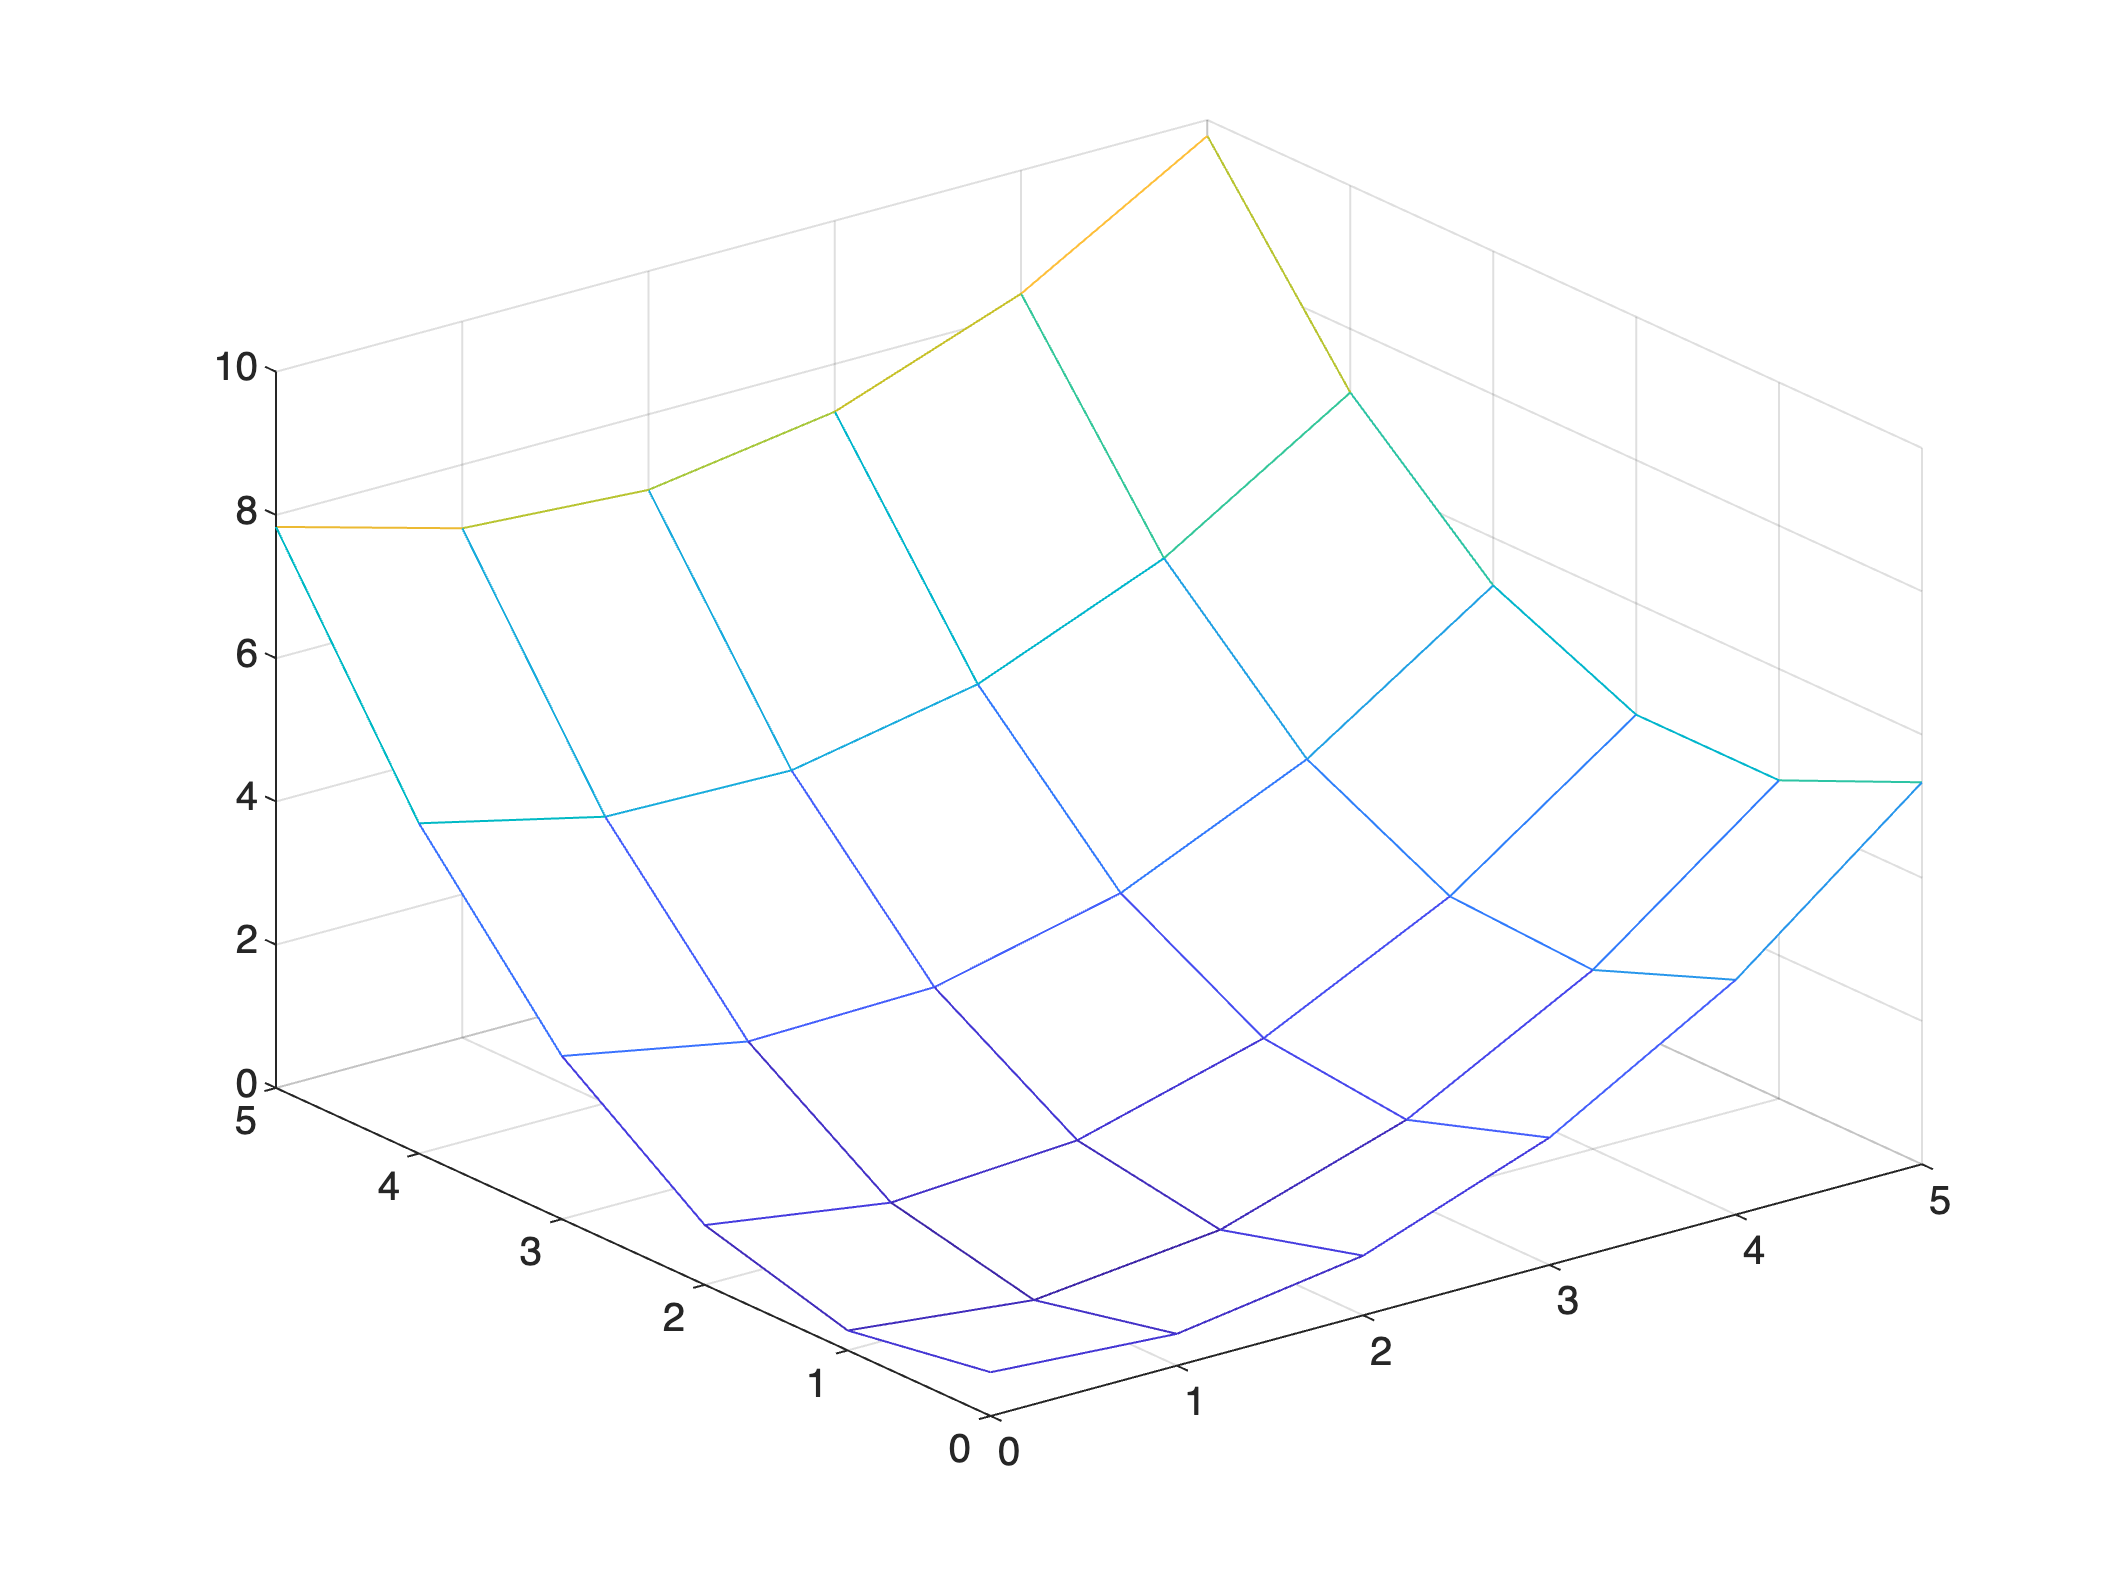

%Compruebo que es 0 en el punto de equilibrio y positiva definida en el
%resto.
[X, Y] = meshgrid(0:1:5);
mesh(X, Y, subs(V, {x1, x2}, {X, Y}))

La función V calculada cumple las condiciones necesarias para ser función de Lyapunov.

%Sigo con esta, que es más simple.
V = (x1 - 1)^2/2 + (x2 - 1)^2/2

$$V = \frac{{\left(x_{1}-1\right)}^{2}}{2}+\frac{{\left(x_{2}-1\right)}^{2}}{2}$$

%Esta función es claramente positiva semidefinida y solo vale 0 en (1 1).
%Calculo la derivada de Lie
dlie = simplify(gradient(V)'*system)

$$dlie = \left(\frac{x_{1}}{x_{2}}-1\right)\,\left(x_{2}-1\right)-\left({x_{1}}^{2}-\frac{1}{x_{2}}\right)\,\left(x_{1}-1\right)$$

La derivada de Lie es 0 en el punto de equilibrio. Voy a buscar dónde es negativa.

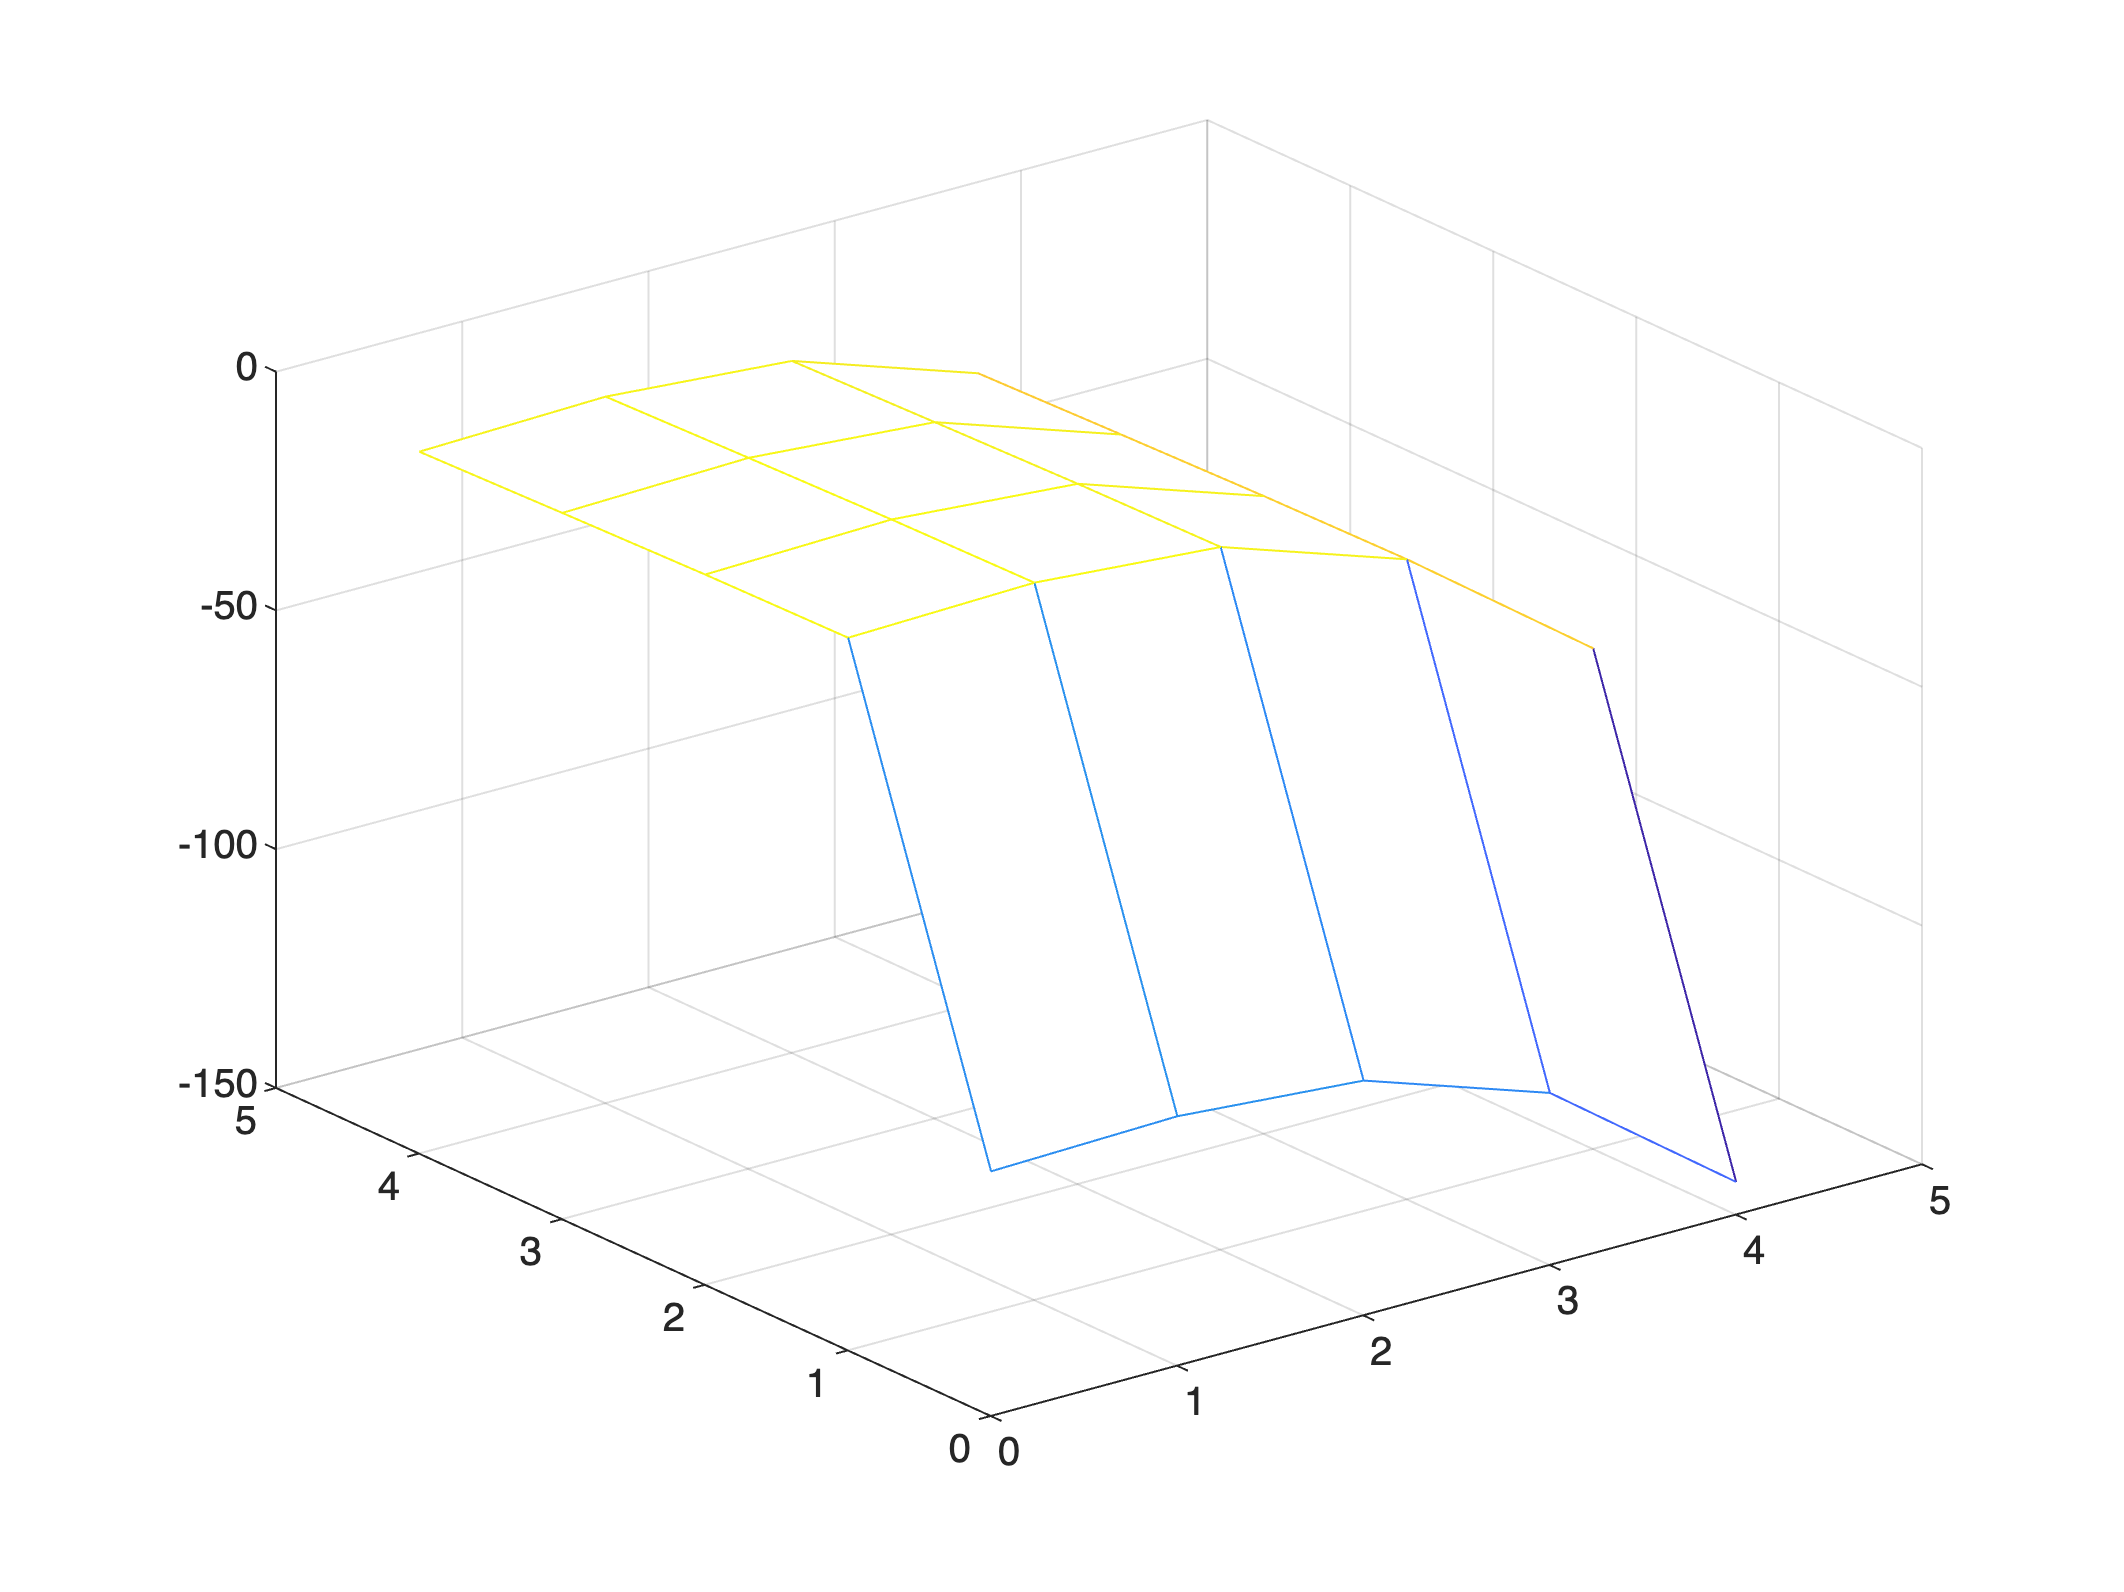

[X, Y] = meshgrid(0.01:1:5);
mesh(X, Y, subs(dlie, {x1, x2}, {X, Y}))

Por lo que se ve, la derivada de Lie es negativa para cualquier valor positivo de x1 y x2, exceptuando el punto de equilibrio (1 1), donde vale 0, esto quiere decir que todos los puntos (al menos en la vecindad del punto de equilibrio) convergerán al mismo.

## Apartado c)

Ahora vamos a comprobar que todo va bien.

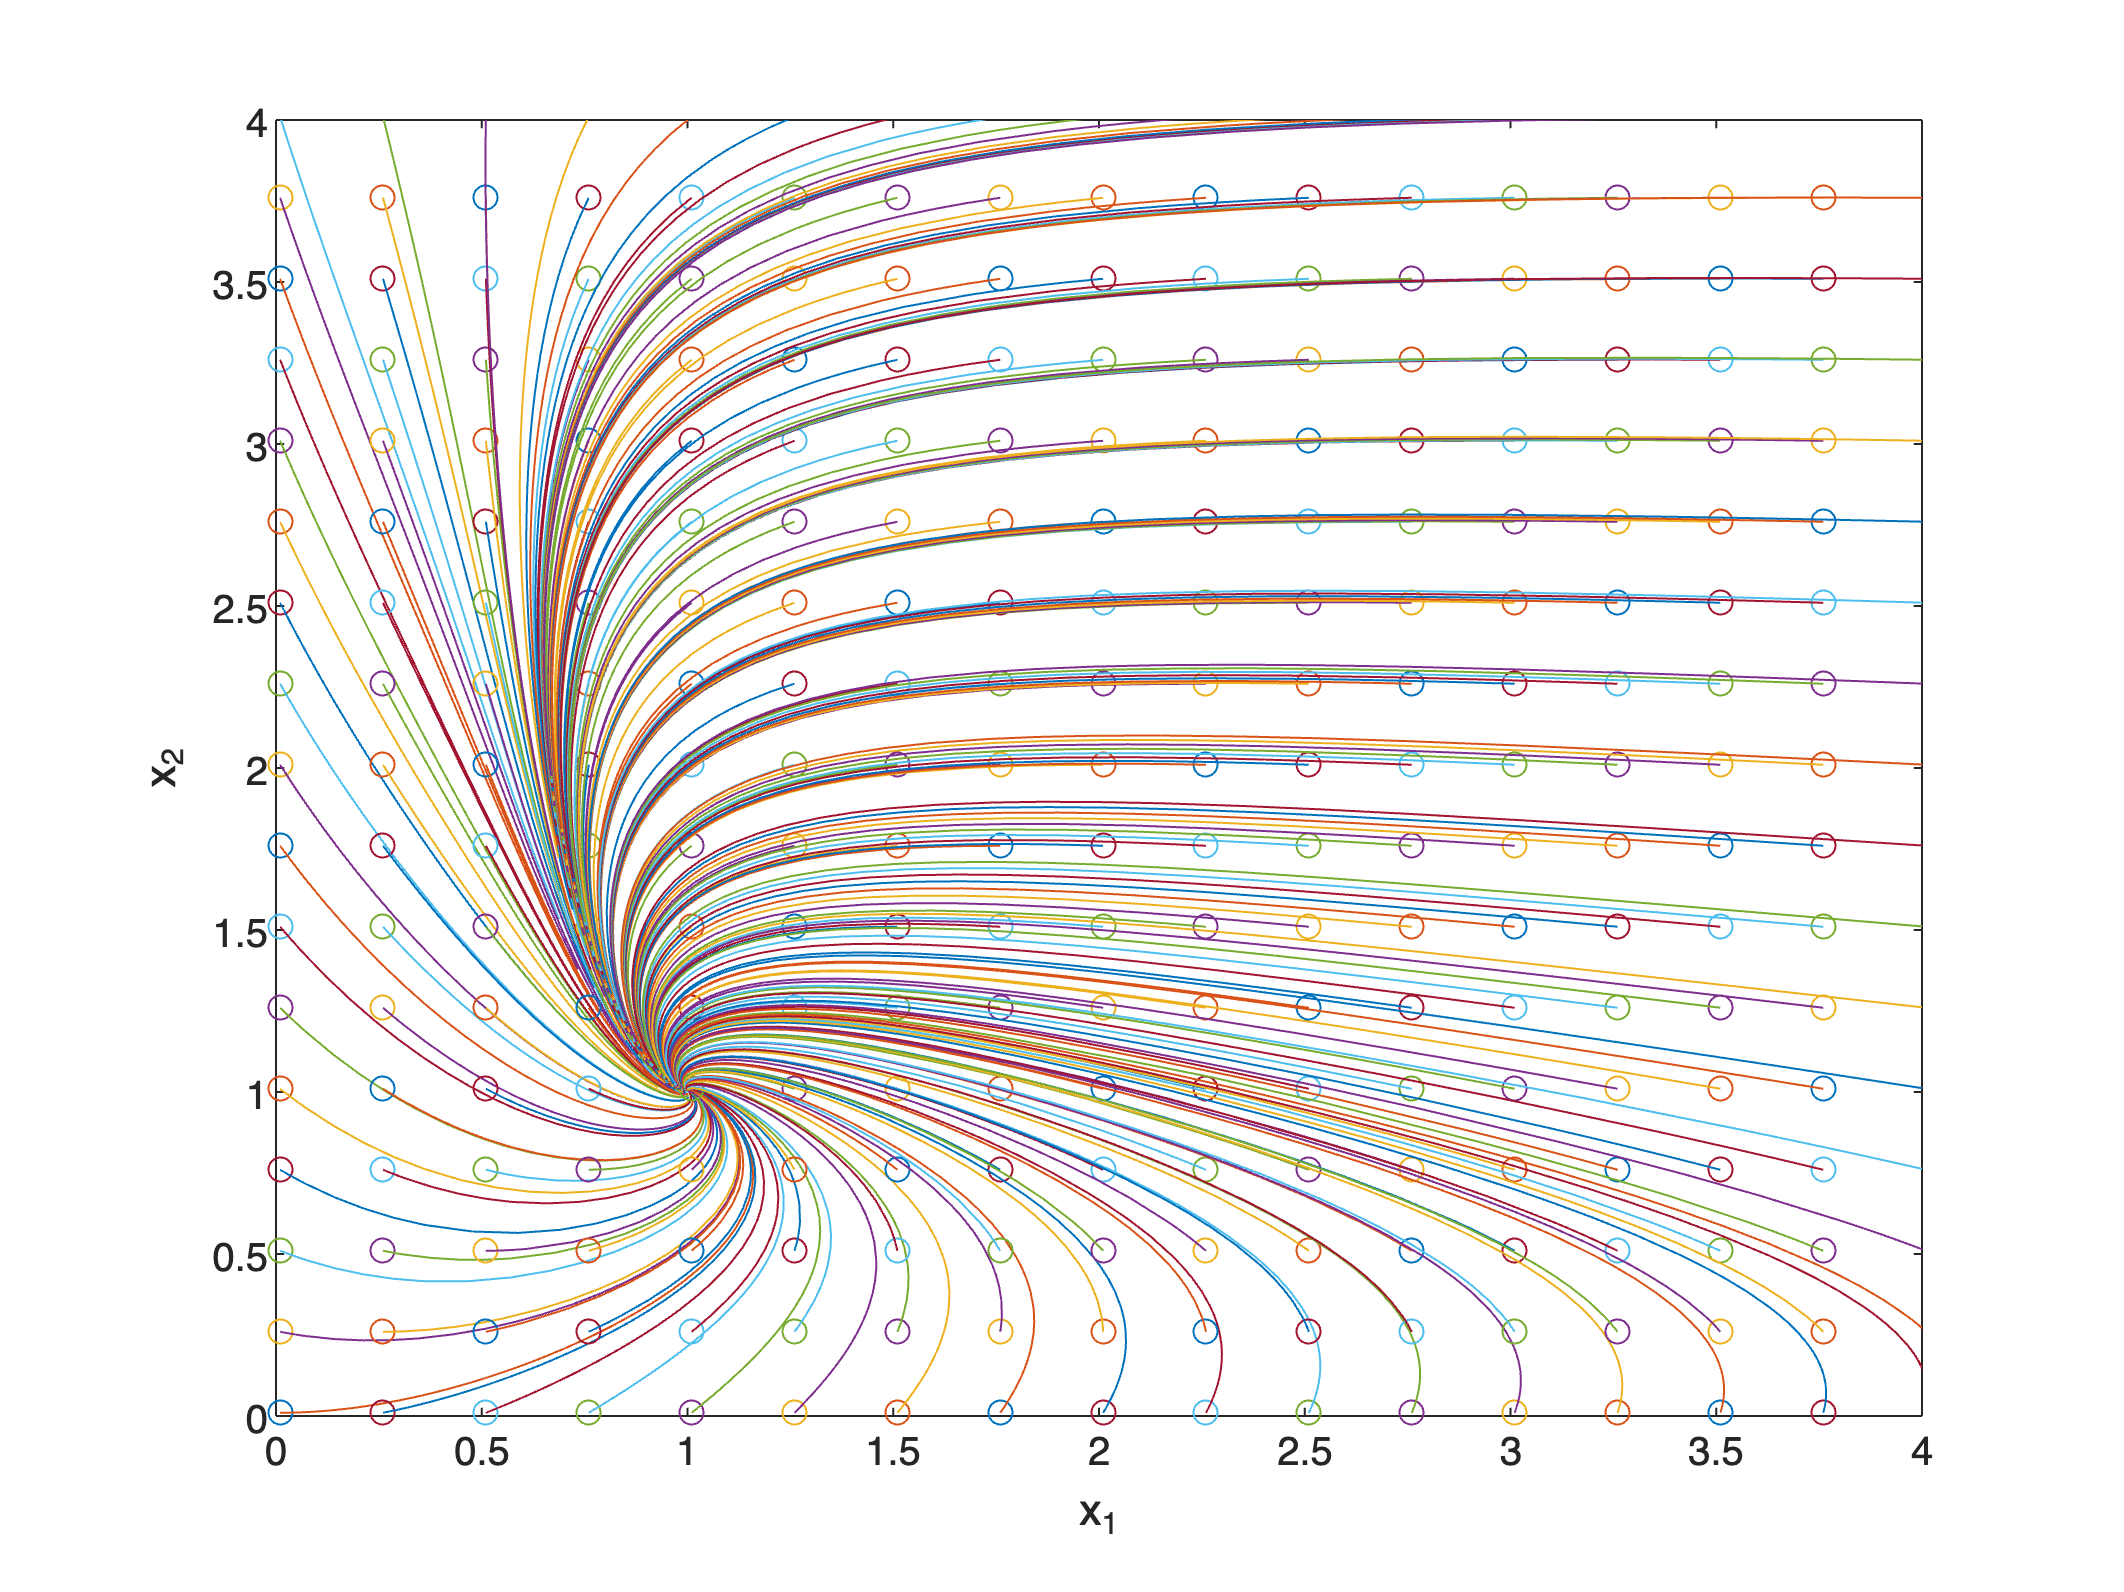

figure;
for i = 0.01:0.25:4.01 %No incluyo el 0 porque no entra en el conjunto R+ 
    for j = 0.01:0.25:4.01
       [t, x] = ode45(@sys1, [0 3], [i; j]);
       plot(i, j, "o"); hold on;
       plot(x(:,1), x(:,2));
       xlim([0 4]);
       ylim([0 4]);
       xlabel("x_1")
       ylabel("x_2")
    end
end
hold off;

En el diagrama de fases se aprecia claramente que todos los puntos terminan convergiendo al punto (1 1), lo cual es coherente con el análisis realizado previamente por Lyapunov. 

# Ejercicio 2 Parcial 2

## Apartado a)

%Como antes, defino el sistema
syms x1 x2 b u K real %Redefino x1 y x2 ahora como reales, no necesariamente positivos. La entrada u es un escalar real. 
system2(1, 1) = x2;
system2(2, 1) = -x1 - x2*(x1^2 + b) + u;
system2

$$system2 = \left(\begin{array}{c} x_{2}\\ u-x_{1}-x_{2}\,\left({x_{1}}^{2}+b\right) \end{array}\right)$$

%Encuentro los puntos de equilibrio de nuevo. 
[x10, x20] = solve(system2, [x1, x2]);
x0 = [x10; x20]

$$x0 = \left(\begin{array}{c} u\\ 0 \end{array}\right)$$

Particularmente, para el sistema no forzado

x0a = [0; 0]

x0a =      0
     0


Tiene sentido que el punto de equilibrio no dependa de b en absoluto, ya que, para igualar a 0 la primera ecuación, x2 debe necesariamente ser 0, de manera que a la hora de igualar la segunda ecuación a 0 manteniendo esta condición, el paréntesis x1^2 + b queda al estar multiplicado por x2 = 0. 

Voy a mirar la estabilidad. Voy a hacerlo con la función de Lyapunov. 

V2 = (x1^2 + x2^2)/2

$$V2 = \frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}$$

%Calculo la derivada de Lie
dlie2 = expand(gradient(V2)' * system2)

$$dlie2 = -{x_{1}}^{2}\,{x_{2}}^{2}-b\,{x_{2}}^{2}+u\,x_{2}$$

El primer término siempre es negativo. Asumiendo el sistema no forzado (u = 0), se tiene que para cualquier b positiva el punto de equilibrio es estable. Sin embargo, para valores negativos de b, solo habrá convergencia en regiones tales que x1^2 > |`b`|, es decir, no se puede converger al punto de equilibrio porque está en el origen y conforme decrezca x1 la derivada de Lie se hará positiva mientras. Se cumple que tanto la función de Lyapunov como la derivada de Lie son 0 en el punto de equilibrio (0 0) (y la derivada de Lie también lo cumple para valores de entrada no nula).  

## Apartado b)

%El sistema pasaría a tener la forma
system2(2, 1) = -x1 - x2*(x1^2 + b) - K*x2;
system2 %Punto de equilibrio (0 0). 

$$system2 = \left(\begin{array}{c} x_{2}\\ -x_{1}-K\,x_{2}-x_{2}\,\left({x_{1}}^{2}+b\right) \end{array}\right)$$

dlie2 = expand(gradient(V2)' * system2) 

$$dlie2 = -{x_{1}}^{2}\,{x_{2}}^{2}-K\,{x_{2}}^{2}-b\,{x_{2}}^{2}$$

Viendo directamente la forma de la derivada de Lie, se puede observar que esta puede hacerse negativa para todos los puntos en R^2 menos (0 0) (en donde valdrá 0 independientemente de b y u) si imponemos una u = -K(x2)^2 tal que K > |`b`|, puesto que de esta manera, la derivada de Lie no tendrá nunca valores positivos independientemente de x1 y x2, es decir, -(x2)^2·(K + b)  < 0 para cualquier x2. 

Si K = b, se corre el riesgo de entrar en estabilidad marginal cuando x1 o x2 sean 0. 

%Se podría confirmar esta idea linealizando en torno a 0 0 y viendo los
%autovalores del jacobiano en este punto
expand(eig(subs(jacobian(system2, [x1, x2]), {x1, x2}, {0, 0}))) %Esto es bastante complicado de ver. 

$$ans = \left(\begin{array}{c} -\frac{K}{2}-\frac{b}{2}-\frac{\sqrt{K^{2}+2\,K\,b+b^{2}-4}}{2}\\ \frac{\sqrt{K^{2}+2\,K\,b+b^{2}-4}}{2}-\frac{b}{2}-\frac{K}{2} \end{array}\right)$$

Nótese que no basta con estudiar solo la derivada de Lie en este caso, porque para cualquier valor de K que se imponga, si x2 vale 0, la derivada valdrá 0 también, independientemente del valor de x1, no pudiéndose concluir gran cosa. De modo que vuelvo al sistema para ver qué ocurre en este caso:

- Si x1 = 0 y x2 = 0, el sistema está ya en el punto de equilibrio.

- Si x1 no es 0 y x2 sí es 0, no está en el punto de equilibrio, pero tampoco encuentra estabilidad. Viendo la ecuación 2 del sistema

expand(system2(2, 1)) %con K positiva y mayor que |b|

$$ans = -x_{2}\,{x_{1}}^{2}-x_{1}-K\,x_{2}-b\,x_{2}$$

Resulta que, para valores nulos de x2, $\dot{\;x_2 } =-x_1$ , de modo que, mientras x1 no sea 0 (es decir, no se está en el punto de equilibrio), habrá un incremento en x2 que moverá el sistema de x2 = 0 a x2 = dx2. Independientemente de si este incremento es positivo o negativo, gracias a la realimentación, el sistema convergerá al punto de equilibrio. 

## Apartado c)

Tenemos que |b| = 1 (b = -1), así que vamos a imponer que K sea mayor a 1 (K = 2), de modo que para cualquier x2, la entrada supere la influencia de b en el sistema. 

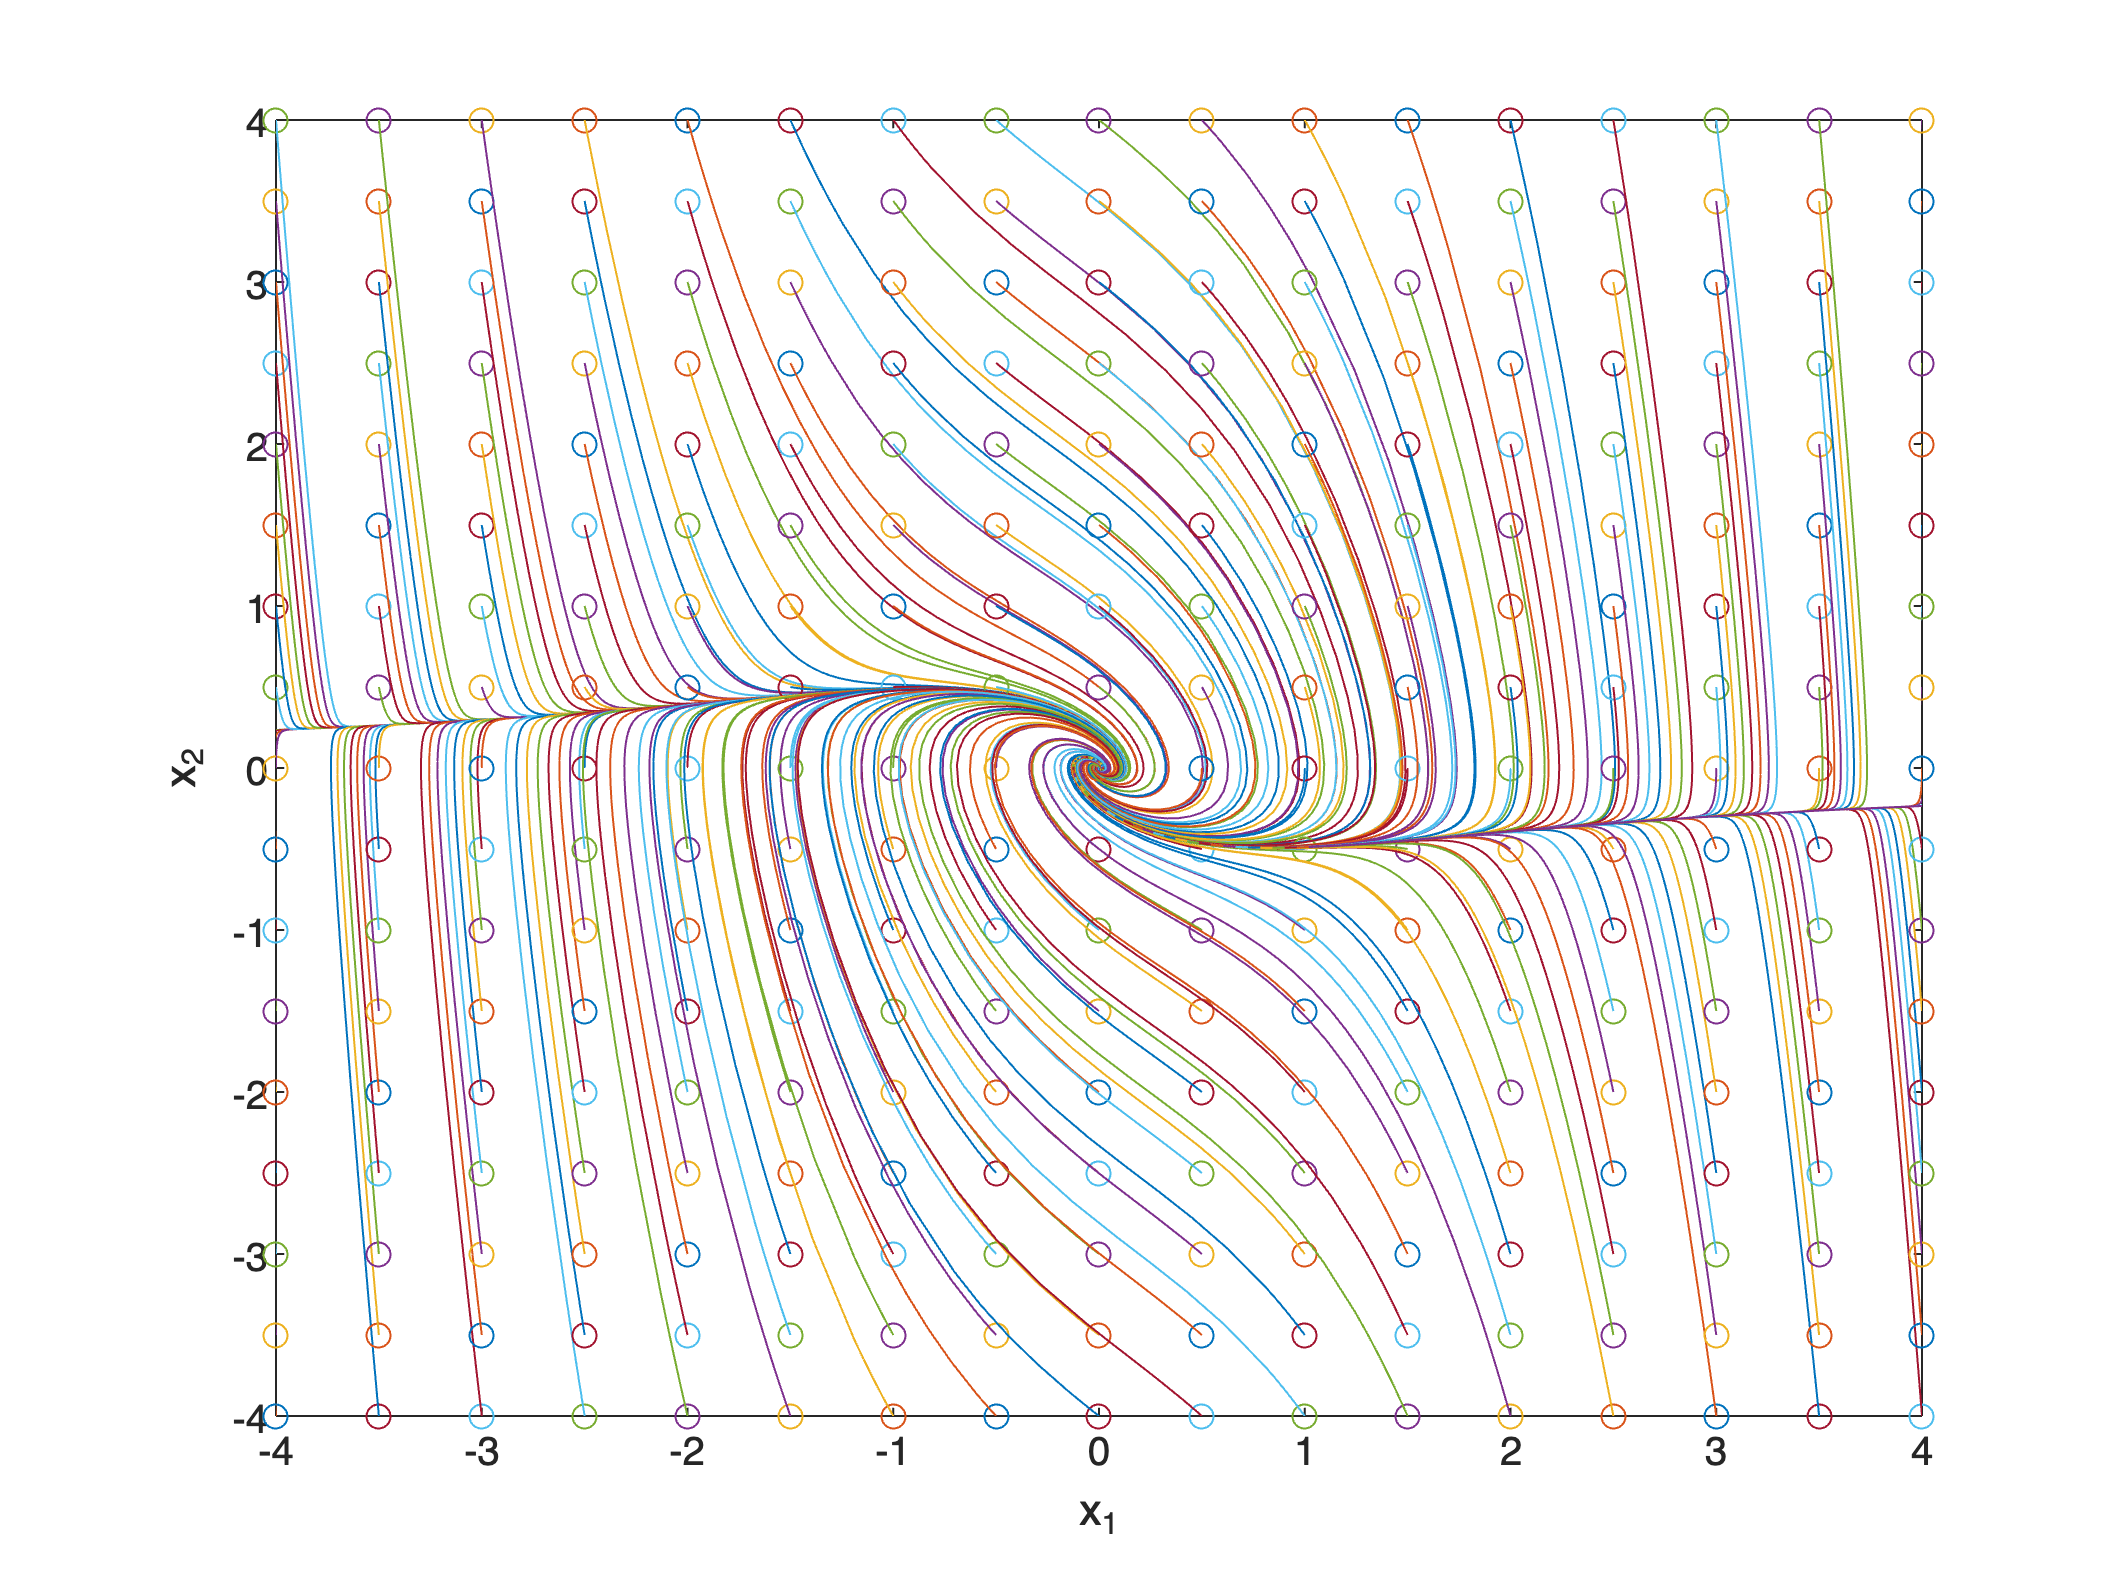

figure;
for i = -4:0.5:4
    for j = -4:0.5:4
        [t, x] = ode45(@(t, x)sys2(t, x, -1, 2), [0 10], [i; j]); %Simulo para b = -1, K = 2
        plot(i, j, "o"), hold on;
        plot(x(:, 1), x(:, 2));
        xlim([-4 4])
        ylim([-4 4])
        xlabel("x_1")
        ylabel("x_2")
    end
end
hold off;

Alargando el tiempo de simulación, todas las trayectorias se acercan cada vez más a 0, lo que parece indicar que efectivamente, se ha logrado la estabilidad asintótica con esta realimentación. 

function ydot = sys1(t, y) %Sistema ejercicio 1
    ydot(1, 1) = -y(1, 1)^2 + 1/y(2, 1);
    ydot(2, 1) = y(1, 1)/y(2, 1) - 1;
end

function ydot2 = sys2(t, y, b, k) %Sistema ejercicio 2
    ydot2(1, 1) = y(2, 1);
    ydot2(2, 1) = -y(1, 1) - y(2, 1)*(y(1, 1)^2 + b) - k*y(2, 1);
end
